ir_lens = [128, 256, 512, 1024];
[target, ref] = recorded_samples();

Iteration 1/10
Iteration 2/10
Iteration 3/10
Iteration 4/10
Iteration 5/10
Iteration 6/10
Iteration 7/10
Iteration 8/10
Iteration 9/10
Iteration 10/10


   1.0e-07 *

    0.5337    0.4979    0.4974    0.4971    0.4969    0.4968    0.4967    0.4966    0.4966    0.4965



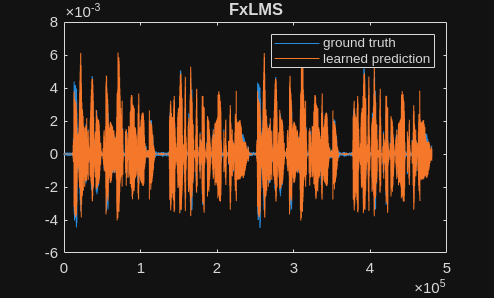

Iteration 1/10
Iteration 2/10
Iteration 3/10
Iteration 4/10
Iteration 5/10
Iteration 6/10
Iteration 7/10
Iteration 8/10
Iteration 9/10
Iteration 10/10


   1.0e-07 *

    0.7474    0.6628    0.6609    0.6605    0.6602    0.6601    0.6599    0.6598    0.6597    0.6596



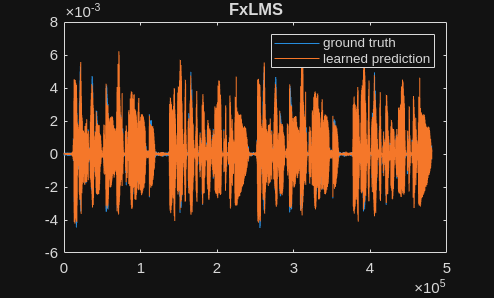

Iteration 1/10
Iteration 2/10
Iteration 3/10
Iteration 4/10
Iteration 5/10
Iteration 6/10
Iteration 7/10
Iteration 8/10
Iteration 9/10
Iteration 10/10


   1.0e-06 *

    0.1151    0.1047    0.1044    0.1044    0.1044    0.1044    0.1044    0.1044    0.1044    0.1044



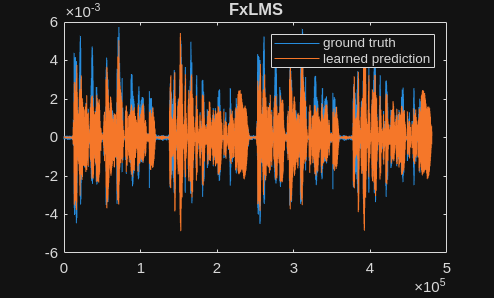

Iteration 1/10
Iteration 2/10
Iteration 3/10
Iteration 4/10
Iteration 5/10
Iteration 6/10
Iteration 7/10
Iteration 8/10
Iteration 9/10
Iteration 10/10


   1.0e-06 *

    0.1263    0.1097    0.1085    0.1081    0.1079    0.1078    0.1077    0.1076    0.1076    0.1075



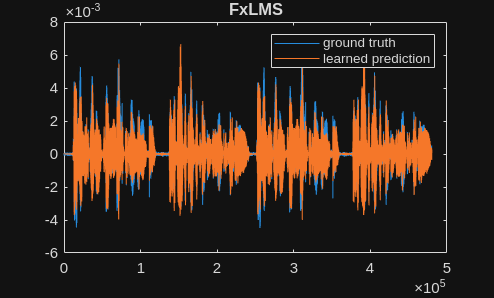

N = length(ir_lens);
n_iter = 10;
mse_lens = zeros(N, n_iter);
preds = zeros(N, length(target));

for i = 1:N
    ir_len = ir_lens(i);
    source_to_ref_cm = 2;
    panel_ir = clipped_irs(ir_len, source_to_ref_cm);
    filter_order = ir_len * 2;
    
    step_size = 0.05;

    fxlms = FxLMS(ref, target, panel_ir, filter_order, step_size);
    fxlms.gpu = false;
    [pred_i, mses_i] = fxlms.learn(n_iter, false);

    mse_lens(i, :) = mses_i;
    preds(i, :) = pred_i;
    
    disp(mses_i)
    fxlms.results_plot();

end

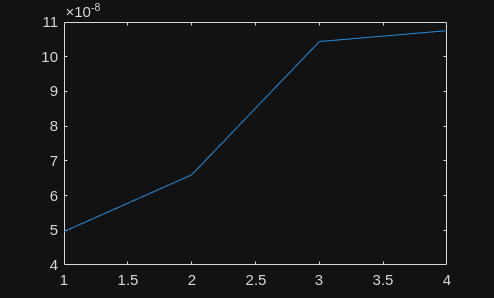

figure
plot(mse_lens(:, end))

Iteration 1/10
Iteration 2/10
Iteration 3/10
Iteration 4/10
Iteration 5/10
Iteration 6/10
Iteration 7/10
Iteration 8/10
Iteration 9/10
Iteration 10/10


   1.0e-06 *

    0.4255    0.2949    0.2857    0.3046    0.3289    0.3516    0.3710    0.3872    0.4006    0.4118



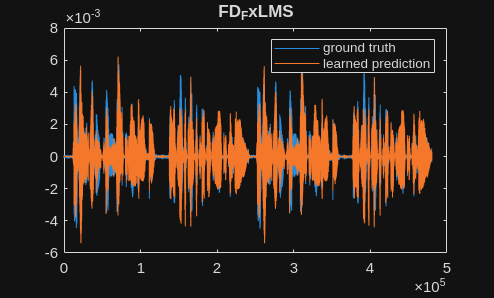

Iteration 1/10
Iteration 2/10
Iteration 3/10
Iteration 4/10
Iteration 5/10
Iteration 6/10
Iteration 7/10
Iteration 8/10
Iteration 9/10
Iteration 10/10


   1.0e-06 *

    0.3844    0.2151    0.1737    0.1587    0.1517    0.1479    0.1456    0.1441    0.1432    0.1425



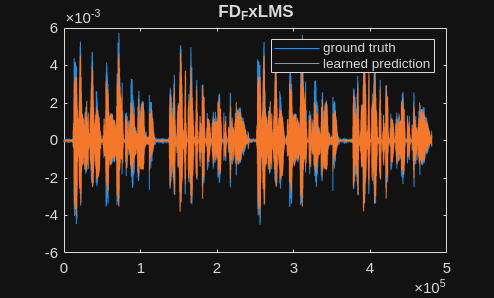

Iteration 1/10
Iteration 2/10
Iteration 3/10
Iteration 4/10
Iteration 5/10
Iteration 6/10
Iteration 7/10
Iteration 8/10
Iteration 9/10
Iteration 10/10


   1.0e-06 *

    0.4288    0.2879    0.2467    0.2317    0.2257    0.2230    0.2217    0.2209    0.2202    0.2197



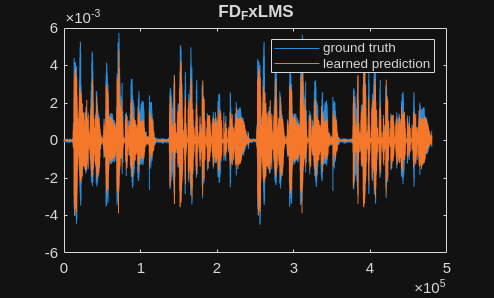

Iteration 1/10
Iteration 2/10
Iteration 3/10
Iteration 4/10
Iteration 5/10
Iteration 6/10
Iteration 7/10
Iteration 8/10
Iteration 9/10
Iteration 10/10


   1.0e-06 *

    0.4378    0.3052    0.2645    0.2456    0.2356    0.2300    0.2265    0.2242    0.2226    0.2214



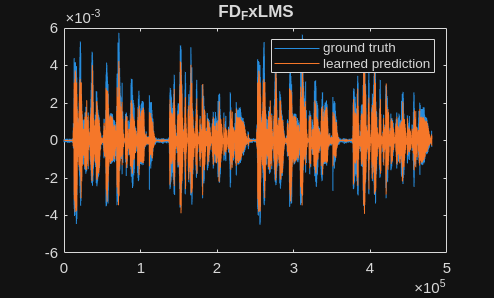

block_len = 128;
for i = 1:N
    ir_len = ir_lens(i);
    source_to_ref_cm = 2;
    panel_ir = clipped_irs(ir_len, source_to_ref_cm);
    filter_order = ir_len * 2;
    
    step_size = 0.1;

    fd_fxlms = FD_FxLMS(ref, target, panel_ir, filter_order, step_size, block_len);
    fd_fxlms.gpu = false;
    [pred_i, mses_i] = fd_fxlms.learn(n_iter, false);

    mse_lens(i, :) = mses_i;
    preds(i, :) = pred_i;
    
    disp(mses_i)
    fd_fxlms.results_plot();

end

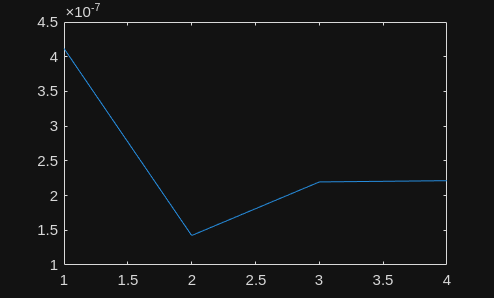

figure
plot(mse_lens(:, end))

[target, ref] = recorded_samples();

cutoff = 400;
fs = 48000;

target = highpass(target, cutoff, fs);
ref = highpass(ref, cutoff, fs);


Iteration 1/10
Iteration 2/10
Iteration 3/10
Iteration 4/10
Iteration 5/10
Iteration 6/10
Iteration 7/10
Iteration 8/10
Iteration 9/10
Iteration 10/10


   1.0e-07 *

    0.1119    0.0639    0.0635    0.0633    0.0631    0.0630    0.0629    0.0628    0.0628    0.0627



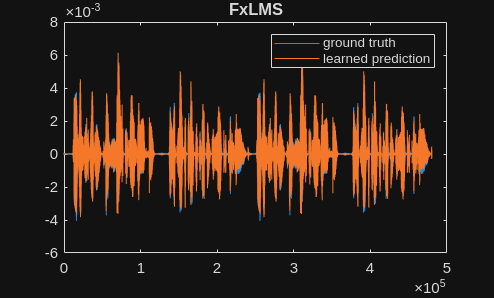

Iteration 1/10
Iteration 2/10
Iteration 3/10
Iteration 4/10
Iteration 5/10
Iteration 6/10
Iteration 7/10
Iteration 8/10
Iteration 9/10
Iteration 10/10


   1.0e-07 *

    0.2780    0.2005    0.1995    0.1996    0.1995    0.1994    0.1992    0.1991    0.1991    0.1990



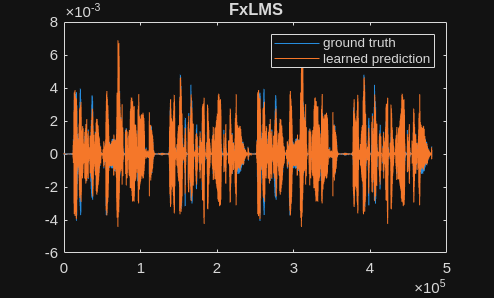

Iteration 1/10
Iteration 2/10
Iteration 3/10
Iteration 4/10
Iteration 5/10
Iteration 6/10
Iteration 7/10
Iteration 8/10
Iteration 9/10
Iteration 10/10


   1.0e-07 *

    0.3529    0.2160    0.2069    0.2052    0.2053    0.2058    0.2064    0.2070    0.2075    0.2080



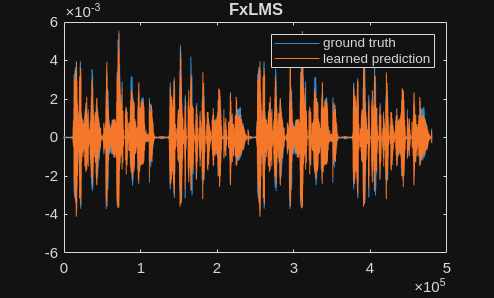

Iteration 1/10
Iteration 2/10
Iteration 3/10
Iteration 4/10
Iteration 5/10
Iteration 6/10
Iteration 7/10
Iteration 8/10
Iteration 9/10
Iteration 10/10


   1.0e-07 *

    0.4833    0.2814    0.2350    0.2164    0.2072    0.2020    0.1990    0.1971    0.1959    0.1951



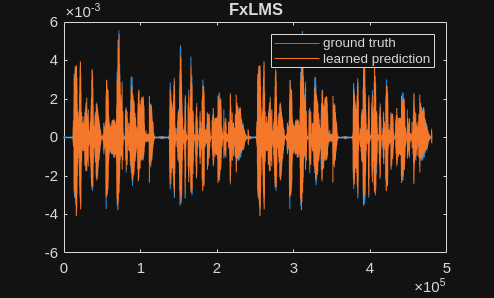

N = length(ir_lens);
n_iter = 10;
mse_lens = zeros(N, n_iter);
preds = zeros(N, length(target));


for i = 1:N
    ir_len = ir_lens(i);
    source_to_ref_cm = 2;

    panel_ir = clipped_irs(ir_len, source_to_ref_cm);

    panel_ir = highpass(panel_ir, cutoff, fs);


    filter_order = ir_len * 2;
    
    step_size = 0.05;

    fxlms = FxLMS(ref, target, panel_ir, filter_order, step_size);
    fxlms.gpu = false;
    [pred_i, mses_i] = fxlms.learn(n_iter, false);

    mse_lens(i, :) = mses_i;
    preds(i, :) = pred_i;
    
    disp(mses_i)
    fxlms.results_plot();

end

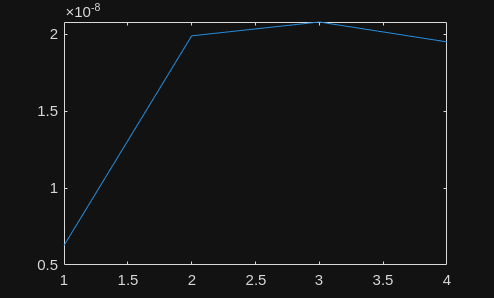

figure
plot(mse_lens(:, end))